## ESERCIZIO I 

%  Rappresentare graficamente tramite diagramma di dispersione
% i dati riportati di seguito
% Nome   X    Y
% A  10 2
% B  12 4
% C 11 3
% D 15 5
% E 16 8
% Aggiungere al diagramma di dispersione il nome di ciascun punto.
% Calcolare la matrice delle distanze Euclidee e di Mahalanobis di queste 5
% osservazioni.
% Mostrare le matrici in formato table tramite disp.

## Soluzione

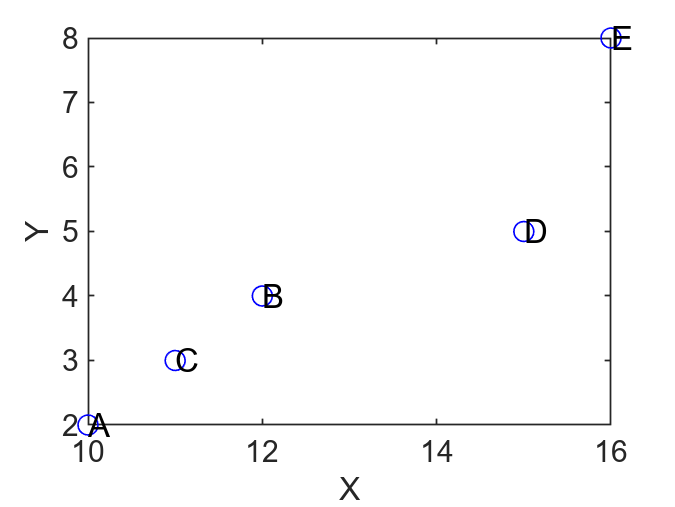

X=[10 2; 12 4; 11 3; 15 5; 16 8];
assi = {'X' 'Y'};
% punti = string array di dimensione 5x1 che contiene le etichette dei
% punti
punti = string(('A':'E')');
figure;
plot(X(:,1),X(:,2),'o','MarkerEdgeColor','b');
text(X(:,1),X(:,2),punti);
xlabel(assi(1))
ylabel(assi(2))


% Matrice distanze Euclidee e di Mahalanobis
M=squareform(pdist(X,'mahalanobis'));
Mtable=array2table(M,'RowNames',punti,'VariableNames',punti);
disp('Distanze di Mahalanobis')

Distanze di Mahalanobis


disp(Mtable)

            A          B          C         D         E   
         _______    _______    _______    ______    ______

    A          0    0.87811    0.43906    2.4446    2.6343
    B    0.87811          0    0.43906    2.2388    1.7562
    C    0.43906    0.43906          0    2.3024    2.1953
    D     2.4446     2.2388     2.3024         0    2.7768
    E     2.6343     1.7562     2.1953    2.7768         0




E=squareform(pdist(X));
Etable=array2table(E,'RowNames',punti,'VariableNames',punti);
disp('Distanze Euclidee')

Distanze Euclidee


disp(Etable)

           A         B         C         D         E   
         ______    ______    ______    ______    ______

    A         0    2.8284    1.4142     5.831    8.4853
    B    2.8284         0    1.4142    3.1623    5.6569
    C    1.4142    1.4142         0    4.4721    7.0711
    D     5.831    3.1623    4.4721         0    3.1623
    E    8.4853    5.6569    7.0711    3.1623         0



% Come era chiaro dal grafico, la massima distanza è fra le unità A ed E.
% La coppia di unità più simili è (A,C)

## ESERCIZIO II

Utilizzando il seed 1000 generare una matrice di dimensione 10x3 di numeri provenienti dalla distribuzione normale con media 5 e varianza 10. Denominare questa matrice con le prime 3 lettere del proprio cognome.

Calcolare la distanza Euclidea e la distanza di Mahalanobis tra la riga 2 e la riga 9 di questa matrice. Mostrare i risultati tramite la funzione disp.


rng(1000)
RIA=sqrt(10)*randn(10,3)+5;
% dM è la matrice delle distanze di Mahalanobis di dimensione 10x10
% L'entrata i,j di questa matrice è la distanza di Mahalanobis tra la riga
% i e la riga j, i,j=1,2, ..., n.
% In questo esempio n=10
dM=squareform(pdist(RIA,"mahalanobis"));
dM29=dM(2,9);
dE=squareform(pdist(RIA,"euclidean"));
dE29=dE(2,9);
disp(['Distanza di Mahalanobis tra la riga due e la riga nove :' num2str(dM29)])

Distanza di Mahalanobis tra la riga due e la riga nove :2.7486


disp(['Distanza Euclidea tra la riga due e la riga nove :' num2str(dE29)])

Distanza Euclidea tra la riga due e la riga nove :8.0018



% Oppure invece che calcolare l'intera matrice delle distanze si estrae la
% riga 2 e la riga 9 e si calcola la distanza Euclidea tra queste due righe
% Si noti che l'output di pdist in questo caso è uno scalare di conseguenza
% non c'è bisogno di fare squareform
dEchk=pdist(RIA([2 9],:));

% Nel caso della distanza di Mahalanonis se alla funzione pdist si passa
% solo la riga 2 e la riga 9 della matrice dei dati RIA, occorre fornire
% come terzo argomento di input di pdist la matrice di covarianze delle
% variabili originarie
S=cov(RIA);
dMchk=pdist(RIA([2 9],:),'mahalanobis',S)

dMchk = 2.7486


% Controllo l'uguaglianza delle delle diverse implementazioni
% Si noti la variabile eps è già predefinita da MATLAB
% Più precisamente eps "Floating-point relative accuracy" è 2.2204e-16
assert(abs(dM29-dMchk)<eps,"Errore nel calcolo della distanza di Mahalanobis")
assert(abs(dE29-dEchk)<eps,"Errore nel calcolo della distanza Euclidea")

## ESERCIZIO III

Calcolare la matrice di similarità degli indici di Gower  tra i 3 frigoriferi AEG, BOSCH e IGNIS. Sono disponibili per i 3 frigoriferi informazioni su capacità, prezzo  (variabili quantitative), allarme, dispenser e display (variabili qualitative dicotomiche)

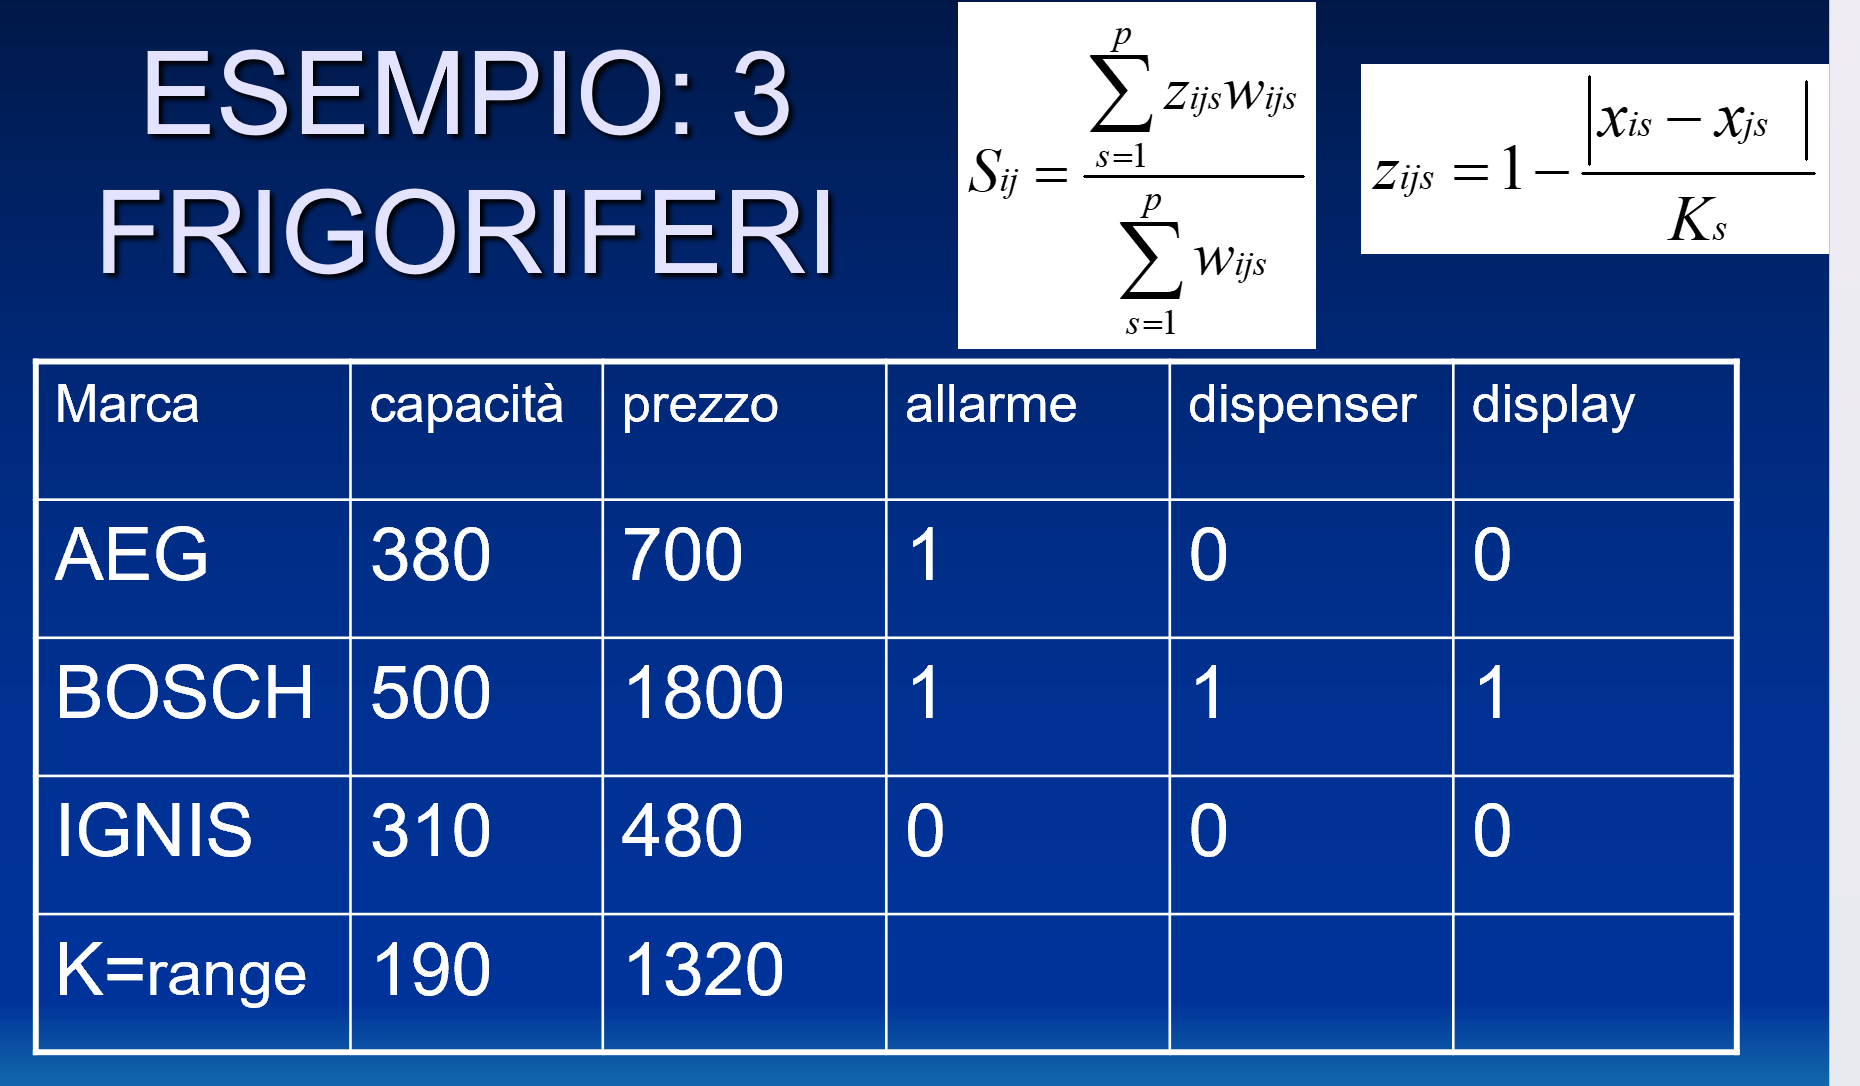

Quali frigoriferi sono tra loro più simili, quali sono quelli meno simili? Mostrare i risultati in formato table.

X=[380	700	    1	0	0
    500	1800	1	1	1
    310	480	    0	0	0  ];
namRighe=["AEG" "BOSCH" "IGNIS"];
namColonne=["capacità" "prezzo" "allarme" "dispenser" "display"];
Xtable=array2table(X,"RowNames",namRighe,"VariableNames",namColonne);

% The first two variables are quantitative and 3:5 are
% dichotomous 
[S,Stable]=GowerIndex(Xtable,'l',[ 1 1 2 2 2]);

disp('Matrice di similarità di Gower')

Matrice di dissimilarità di Gower


disp(Stable)

               AEG       BOSCH     IGNIS 
             _______    _______    ______

    AEG            1    0.30702    0.4883
    BOSCH    0.30702          1         0
    IGNIS     0.4883          0         1



I frigoriferi meno simili sono BOSCH e IGNIS (indice di similarità pari a 0). I frigoriferi più simili solo AEG e IGNIS (similarità pari a 0.4883).

## ESERCIZIO IV

Esercizio: si sono rilevati per 3 clienti una serie di variabili dicotomiche sull'acquisto di determinati beni.

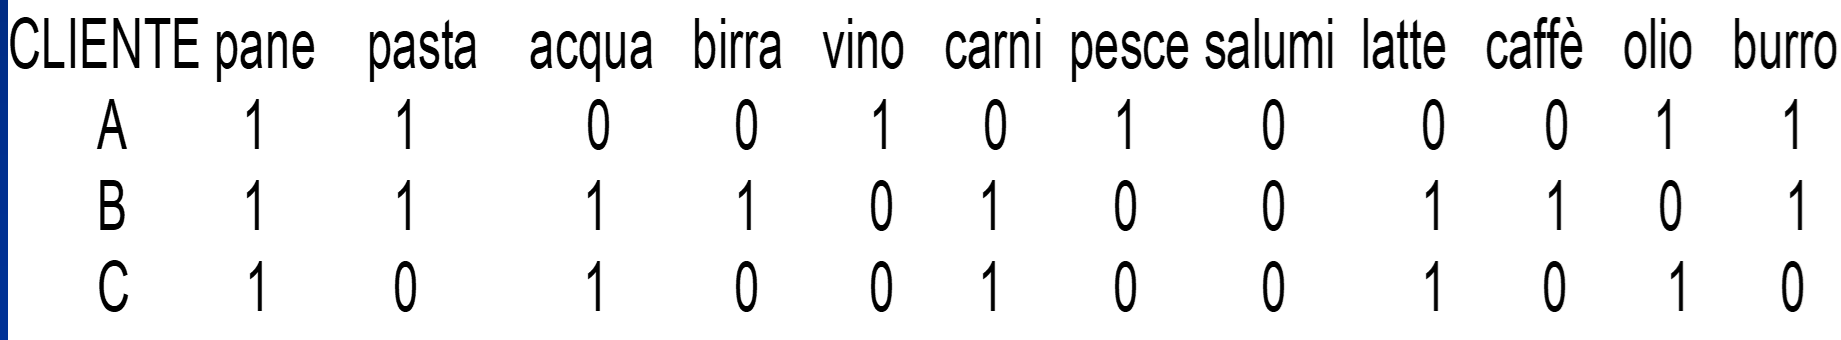

Si calcoli la matrice di similarità degli indici di Jaccard e Sokal Michener

Mostrare l'ouput in formato table con i nomi delle righe e delle colonne.

Commentare la coppia di consumatori più simili e meno simili con entrambi gli indici.

nomiCl=string(('A':'C')');
% Osservazione: nomivar (string array che contiene i nomi delle colonne)
% non è necessario per la risoluzione di questo esercizio
nomivar=["pane" "pasta" "acqua" "birra" "vino" "carni" ...
    "pesce" "salumi" "latte" "caffè" "olio" "burro"];
X=[1 1 0 0 1 0 1 0 0 0 1 1
   1 1 1 1 0 1 0 0 1 1 0 1
   1 0 1 0 0 1 0 0 1 0 1 0];
jac=squareform(1-pdist(X,'jaccard'));
jactable=array2table(jac,"RowNames",nomiCl,"VariableNames",nomiCl);
disp('Matrice degli indici di similarità di Jaccard')

Matrice degli indici di similarità di Jaccard


disp(jactable)

            A          B          C   
         _______    _______    _______

    A          0    0.27273    0.22222
    B    0.27273          0    0.44444
    C    0.22222    0.44444          0




sokmi=squareform(1-pdist(X,'hamming'));
sokmitable=array2table(sokmi,"RowNames",nomiCl,"VariableNames",nomiCl);

disp('Matrice degli indici di similarità di Sokal Michener')

Matrice degli indici di similarità di Sokal Michener


disp(sokmitable)

            A          B          C   
         _______    _______    _______

    A          0    0.33333    0.41667
    B    0.33333          0    0.58333
    C    0.41667    0.58333          0



Entrambi gli indici segnalano che la coppia di consumatori più simili è (B,C).

L'indice di Jaccard segnala che la coppia di consumatori meno simili è (A,C), al contrario l'indice di Sokal Michener segnala che la coppia di consumatori meno simili è (A,B).

In generale, esiste una relazione monotona tra le matrici degli indici di Russel Rao e Jaccard, ma non la matrice degli indici di Sokal Michener.

## ESERCIZIO V

La zona B2:D113 del foglio dati file test_2018.xlsx contiene i punteggi di tre test (d'intelligenza) sostenuti da 112 studenti. 

Dopo aver standardizzato i dati:

1) calcolare le distanze euclidee dal centroide 


$$_2d_{i \overline z}=\sqrt{z_i'z_i} \qquad i=1, 2, \ldots, n$$
  

2) calcolare le distanze di Mahalanobis dal centroide.


$$_Md_{i \overline z}=\sqrt{z_i' R^{-1} z_i}  \qquad i=1, 2, \ldots, n$$
  

3) Calcolare la distanza Euclidea e la distanza di Mahalanobis dal centroide dei 4 punteggi (standardizzati) che seguono

2  2 0

2 -2 0 

-2 -2 0 

-2 2 0 

4) Creare un diagramma di dispersione con le prime due variabili standardizzate. Aggiungere al grafico le prime due coodinate dei 4 punti aggiuntivi. Etichettare i 4 punti con la corrispondente distanza di Mahalanobis.

Commentare la distanza Euclidea e la distanza di Mahalanobis di questi 4 punti.

5) Ripetere il grafico aggiungendo una barra di colore alle distanze Euclidee e di Mahalanobis

Discutere se in questo esempio è preferibile lavorare con le distanze euclidee oppure con le distanze di Mahalanobis. Dire come sarebbero cambiate le distanze di Mahalanobis se avessimo operato sui dati originari (non standardizzati) ed avessimo utilizzato la matrice di covarianze anziché la matrice di correlazione.


$$_Md_{i \overline x}=\sqrt{(x_i -\overline x) ' S^{-1} (x_i -\overline x)}  \qquad i=1, 2, \ldots, n$$
   

% Cancello tutte le variabili dalla memoria
clear
Xtable=readtable('test_2018.xlsx','Sheet','dati','ReadRowNames',true);
X=Xtable{:,:};
% Z= matrice degli scostamenti standardizzati
Z=zscore(X);
% PUNTI 1)-3)
% Calcolo distanze euclidee dal centroide 
% Osservazione: in termini di scostamenti dalla media o degli scostamenti
% standardizzati il centroide è zero.
cent=zeros(1,size(X,2));
R=cov(Z);
% Aggiungo le osservazioni extra
% alla matrice Z
Zextra=[2	2	0
        2	-2	0
        -2	-2	0
        -2	2	0];
Zall=[Z; Zextra];
dE=sqrt(sum(Zall.^2,2));
dM=sqrt(mahalFS(Zall,cent,R));
% Mostro le distanze dell ultime 4 righe (4 osservazioni extra)
dMultime4=dM(end-3:end);
distExtra=[dE(end-3:end) dMultime4];
nomiRighe="PuntoExtra"+string((1:4)');
nomiVar=["Distanze Euclidee" "Distanze di Mahalanobis"];
distExtraT=array2table(distExtra,"RowNames",nomiRighe,'VariableNames',nomiVar);

disp(distExtraT)

                   Distanze Euclidee    Distanze di Mahalanobis
                   _________________    _______________________

    PuntoExtra1         2.8284                  5.0828         
    PuntoExtra2         2.8284                  9.6319         
    PuntoExtra3         2.8284                  5.0828         
    PuntoExtra4         2.8284                  9.6319         



4) Creare un diagramma di dispersione con le prime due variabili standardizzate. Aggiungere al grafico le prime due coodinate dei 4 punti aggiuntivi utilizzando un simbolo ed un colore diverso. Etichettare i 4 punti con il nome della riga (assegnato a piacere) e la corrispondente distanza di Mahalanobis.

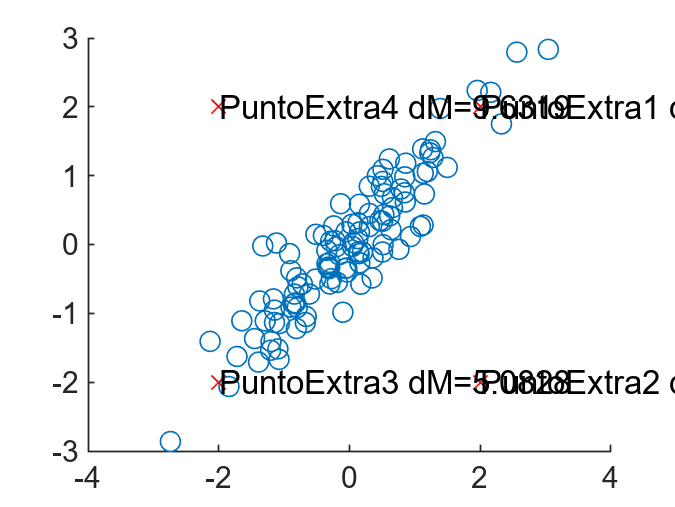

figure
scatter(Z(:,1),Z(:,2))
hold('on')
scatter(Zextra(:,1),Zextra(:,2),'rx')
eti=nomiRighe +" dM=" +string(dMultime4);
text(Zextra(:,1),Zextra(:,2),eti)

Commento: questi 4 punti hanno tutti la stessa distanza Euclidea dal centroide, ma hanno una distanza di Mahalanobis molto diversa. I due punti (2,2) e (-2-2) che si trovano lunga la direzione dove si colloca la maggioranza dei punti presentano una distanza di Mahalanobis molto minore di quella degli altri due 

5) Ripetere il grafico utilizzando cerchi riempiti ed  un colore dei punti che dipende, prima dal valore del quadrato della distanza Euclidea e poi dal valore del quadrato della distanza di Mahalanobis. Aggiungere una colormap di tipo winter e una barra di colore.

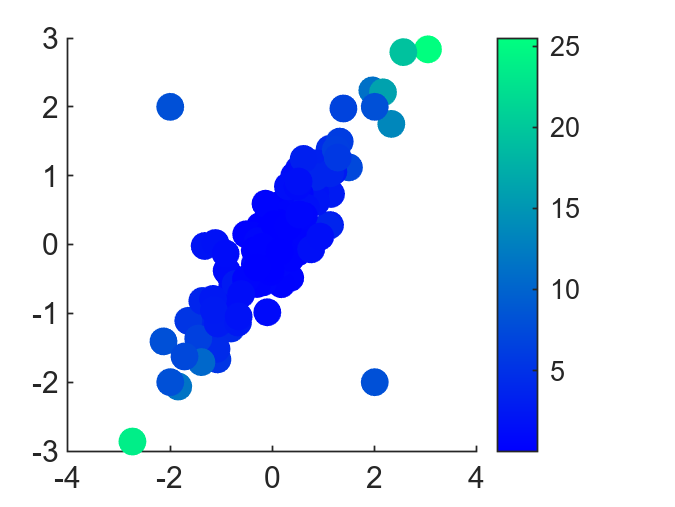

figure
% Diagramma di dispersione con colore che dipende dal quadrato della
% distanza Euclidea dal centroide
scatter(Zall(:,1),Zall(:,2),70,dE.^2,'filled')
colormap winter
colorbar;

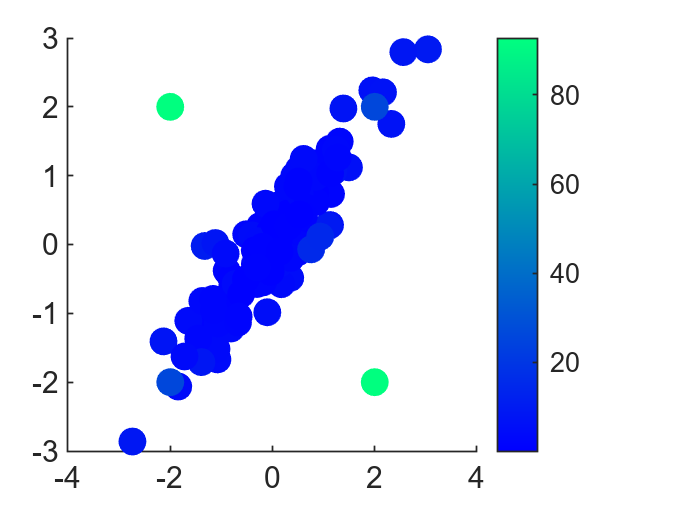


figure
% Diagramma di dispersione con colore che dipende dal quadrato della distanza di
% Mahalanobis dal centroide
scatter(Zall(:,1),Zall(:,2),70,dM.^2,'filled')
colormap winter
colorbar

Se si utilizzando le distanze di Mahalanobis i punti più distanti dal centroide sono quelli che si trovano lontano dalla nuvola dei punti nella direzione opposta a quella di massima variabilità.

Discutere se in questo esempio è preferibile lavorare con le distanze euclidee oppure con le distanze di Mahalanobis. 

E' sicuramente preferibile lavovare con le distanze di Mahalanobis, in quanto questa metrica tiene conto della correlazione tra le diverse variabili.

Dire come sarebbero cambiate le distanze di Mahalanobis se avessimo operato sui dati originari (non standardizzati) ed avessimo utilizzato la matrice di covarianze anziché la matrice di correlazione.

La distanza di Mahalanobis è invariante pre trasformazioni lineari, di conseguenza non sarebbe cambiata.